clear
hr=0;  minu='00';  s_sub='12'; randtimes=50+1;


%---set---

%----
varinam='SMAD';    filenam='SMAD_rand_qua2_';
%
qua25=ceil(25*randtimes/100);  qua75=ceil(75*randtimes/100);


%-----------------
point='A';  load(['smad',s_sub,'_',point,'.mat'])
errsA(1,:)=sort(err(:,2),'descend');   %Vr-u
errsA(2,:)=sort(err(:,7),'descend');   %Zh-u
errsA(3,:)=sort(err(:,1),'descend');   %Vr-v
errsA(4,:)=sort(err(:,6),'descend');   %Zh-v
errsA(5,:)=sort(err(:,3),'descend');   %Vr-qv
errsA(6,:)=sort(err(:,8),'descend');   %Zh-qv
errsA(7,:)=sort(err(:,4),'descend');   %Vr-qr
errsA(8,:)=sort(err(:,9),'descend');   %Zh-qr
%errsA(9,:)=sort(err(:,5),'descend');   %Vr-T
%errsA(10,:)=sort(err(:,10),'descend'); %Zh-T

meanA=mean(errsA,2); qua25A=errsA(:,qua25);  qua75A=errsA(:,qua75);


%----------------
point='B';  load(['smad',s_sub,'_',point,'.mat'])
errsB(1,:)=sort(err(:,2),'descend');   %Vr-u
errsB(2,:)=sort(err(:,7),'descend');   %Vr-v
errsB(3,:)=sort(err(:,1),'descend');   %Vr-qv
errsB(4,:)=sort(err(:,5),'descend');   %Vr-qr
errsB(5,:)=sort(err(:,3),'descend');   %Zh-u
errsB(6,:)=sort(err(:,8),'descend');   %Zh-v
errsB(7,:)=sort(err(:,4),'descend');   %Zh-qv
errsB(8,:)=sort(err(:,9),'descend');   %Zh-qr
%errsB(9,:)=sort(err(:,5),'descend');   %Vr-T
%errsB(10,:)=sort(err(:,10),'descend');  %Zh-T

meanB=mean(errsB,2);  qua25B=errsB(:,qua25);  qua75B=errsB(:,qua75);

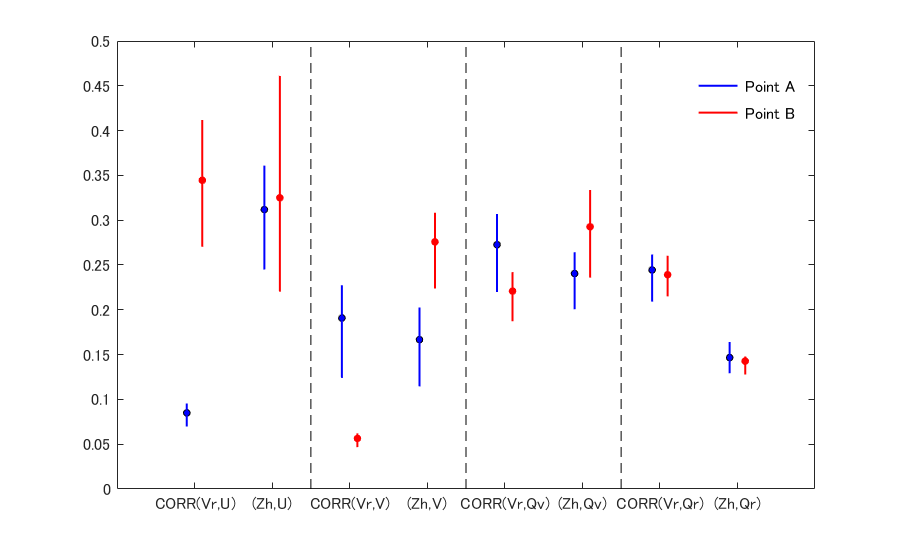

%-----------------
vmn=size(errsA,1);
x=1:vmn;
%---
figure('position',[100 100 900 550])

plot(x-0.1 ,meanA,'ko','MarkerSize',5,'MarkerFaceColor','b'); hold on
plot(x+0.1,meanB,'ro','MarkerSize',5,'MarkerFaceColor','r')
for i=1:vmn
  line([x(i)-0.1 x(i)-0.1],[qua25A(i) qua75A(i)],'color','b','LineWidth',1.5)
  line([x(i)+0.1 x(i)+0.1],[qua25B(i) qua75B(i)],'color','r','LineWidth',1.5)
end
for i=2.5:2:x(end)
line([i i],[0 0.5],'linestyle','--','color','k')
end
line([x(end)-0.5 x(end)],[0.45 0.45],'color','b','LineWidth',1.5); text(x(end)+0.1,0.45,'Point A','color','k','fontsize',12)
line([x(end)-0.5 x(end)],[0.42 0.42],'color','r','LineWidth',1.5); text(x(end)+0.1,0.42,'Point B','color','k','fontsize',12)
%
xtick={'CORR(Vr,U)';'(Zh,U)';'CORR(Vr,V)';'(Zh,V)';'CORR(Vr,Qv)';'(Zh,Qv)';'CORR(Vr,Qr)';'(Zh,Qr)'};
set(gca,'XTick',x,'Xticklabel',xtick,'Xlim',[0 ceil(x(end))+1],'Ylim',[0 0.5],'fontsize',12)

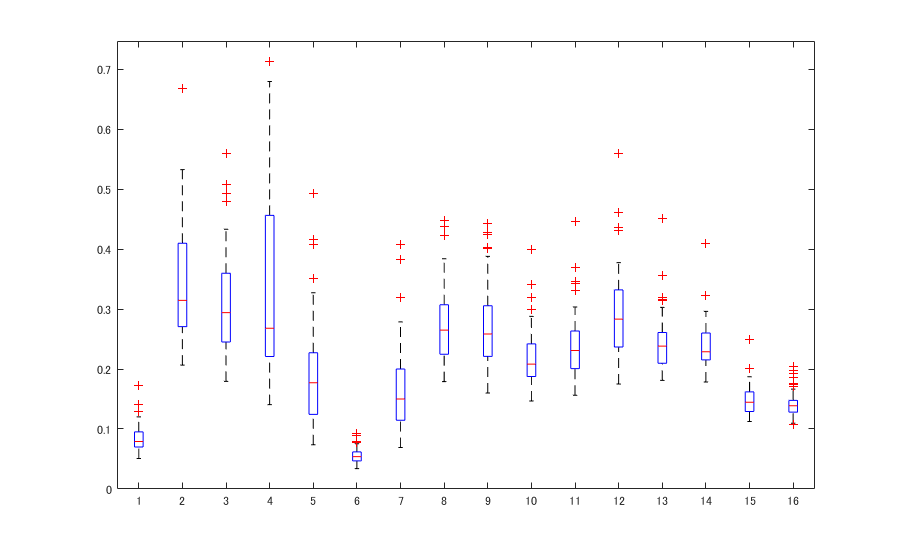

errall=zeros(51,16);
errall(:,1:2:15)=errsA';
errall(:,2:2:16)=errsB';
figure('position',[100 100 900 550])

g=1:16;
boxplot(errall,'whisker',1,'Widths',0.2')


%boxplot(errsB',2:2:16,'whisker',1.5,'BoxStyle','filled','Colors','k')



   %s_hr=num2str(hr,'%.2d');
   %tit=['SMADs ',s_sub,' grid'];
   %title(tit,'fontsize',15)
   %outfile=[outdir,'/',filenam,s_hr,minu,'_sub',s_sub,'_box'];


